%Parametros del Circuito
R = 100 % Resistencia (ohmios)

R = 100

L = 0.1 % Inductancia (henrios)

L = 0.1000

Cap = 1e-6 % Capacitancia (faradios)

Cap = 1.0000e-06

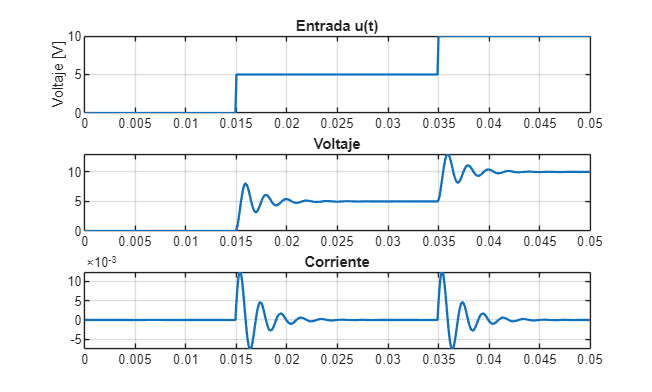



A = [-R/L -1/L; 1/Cap 0]; % Matriz de Estado
B = [1/L; 0]; % Matriz de Entrada
C = [1 0; 0 1]; % Matriz de Salida
D = [0;0]; % Matriz de Transferencia directa


%sys = ss(A,B,C,D);
%subplot(2,1,1);
%step(sys);
%xlabel('Time [s]'); ylabel('Vc [V]');
%subplot(2,1,2);
%impulse(sys);
%xlabel('Time [s]'); ylabel('Vc [V]');

%[num, den] = ss2tf(A,B,C,D);
%[Ap, Bp, Cp, Dp] = tf2ss(num,den);

%ts = 0.015; % Tiempo de simulación
%tspan = [0 ts];
%u = 1; % Voltaje de entrada
%x0 = [0; 0]; % Condiciones iniciales
%[t, X] = ode45(@(t,x) modelRLC(x, A, B, u), tspan, x0);
%y = C * X.' + D * u;

%plot(t,y, 'LineWidth', 2); 
%grid on

% Aquí el código para definir el espacio de estados
function dx = modelRLC(x, A, B, u)
    dx = A * x + B * u; % Ecuación de Estado
end 


ts = 0.0001;    %tiempo de simulacion              
t = (0:ts:0.05)';  

% Código para generar la señal arbitraria
s1 = zeros(1, sum(t < 0.015));                       % 0 V
s2 = ones(1, sum(t >= 0.015 & t < 0.035)) * 5;         % 5 V
s3 = ones(1, sum(t >= 0.035)) * 10;                  % 10 V
arbsig = [s1 s2 s3]';  

t = t(1:length(arbsig));

tspan = [0 ts];

x0 = [0; 0];                    
X = zeros(length(t), 2);        
X(1,:) = x0.';
T = zeros(length(t), 1);        


for k = 2:length(t)
    tspan = [t(k-1) t(k)];
    u_k = arbsig(k);
    [tk, xk] = ode45(@(t,x) modelRLC(x, A, B, u_k), tspan, X(k-1,:)');
    X(k,:) = xk(end,:);
    T(k) = tk(end);
end
...
% Continúa con el cálculo de la salida
Y = X*C';  % Y=C*X + D*U

corriente = Y(:,1);
voltaje = Y(:,2);

%figure;
%subplot(2,1,1);
%plot(t, arbsig);

%subplot(2,1,2);
%plot(t, Y);

figure;

subplot(3,1,1);
plot(t, arbsig, 'LineWidth', 1.4);
title('Entrada u(t)');
ylabel('Voltaje [V]');
grid on;

subplot(3,1,2);
plot(t, voltaje, 'LineWidth', 1.4);
title('Voltaje');
grid on;

subplot(3,1,3);
plot(t, corriente, 'LineWidth', 1.4);
title('Corriente');
grid on;